Function FItting with NN

clc;
close all;
clear ;

Import the Data

data = cell2mat(struct2cell(load('data_NN.mat')))

data =    -2.0000   -2.0341   -2.0694   -2.1058   -2.1433   -2.1820   -2.2219   -2.2629   -2.3051   -2.3483   -2.3927   -2.4382   -2.4846   -2.5319   -2.5800   -2.6288   -2.6782   -2.7280   -2.7780   -2.8280   -2.8779   -2.9273   -2.9761   -3.0239   -3.0706   -3.1157   -3.1591   -3.2003   -3.2391   -3.2752   -3.3083   -3.3380   -3.3640   -3.3862   -3.4041   -3.4176   -3.4264   -3.4303   -3.4292   -3.4228   -3.4111   -3.3940   -3.3716   -3.3438   -3.3109   -3.2729   -3.2301   -3.1829   -3.1316   -3.0766
         0    0.0086    0.0161    0.0226    0.0279    0.0321    0.0351    0.0369    0.0372    0.0362    0.0337    0.0296    0.0239    0.0164    0.0071   -0.0042   -0.0175   -0.0330   -0.0508   -0.0711   -0.0939   -0.1194   -0.1477   -0.1790   -0.2134   -0.2511   -0.2921   -0.3366   -0.3847   -0.4364   -0.4919   -0.5511   -0.6140   -0.6806   -0.7508   -0.8244   -0.9012   -0.9808   -1.0630   -1.1472   -1.2329   -1.3196   -1.4066   -1.4933   -1.5789   -1.6628   -1.7444   -1.8229   -1.8978  

x = data(1:3,1:1000)%Take the input from the data_NN.mat

x =    -2.0000   -2.0341   -2.0694   -2.1058   -2.1433   -2.1820   -2.2219   -2.2629   -2.3051   -2.3483   -2.3927   -2.4382   -2.4846   -2.5319   -2.5800   -2.6288   -2.6782   -2.7280   -2.7780   -2.8280   -2.8779   -2.9273   -2.9761   -3.0239   -3.0706   -3.1157   -3.1591   -3.2003   -3.2391   -3.2752   -3.3083   -3.3380   -3.3640   -3.3862   -3.4041   -3.4176   -3.4264   -3.4303   -3.4292   -3.4228   -3.4111   -3.3940   -3.3716   -3.3438   -3.3109   -3.2729   -3.2301   -3.1829   -3.1316   -3.0766
         0    0.0086    0.0161    0.0226    0.0279    0.0321    0.0351    0.0369    0.0372    0.0362    0.0337    0.0296    0.0239    0.0164    0.0071   -0.0042   -0.0175   -0.0330   -0.0508   -0.0711   -0.0939   -0.1194   -0.1477   -0.1790   -0.2134   -0.2511   -0.2921   -0.3366   -0.3847   -0.4364   -0.4919   -0.5511   -0.6140   -0.6806   -0.7508   -0.8244   -0.9012   -0.9808   -1.0630   -1.1472   -1.2329   -1.3196   -1.4066   -1.4933   -1.5789   -1.6628   -1.7444   -1.8229   -1.8978   -1

y = data(1:3,2:1001)%Take the output from the data_NN.mat

y =    -2.0341   -2.0694   -2.1058   -2.1433   -2.1820   -2.2219   -2.2629   -2.3051   -2.3483   -2.3927   -2.4382   -2.4846   -2.5319   -2.5800   -2.6288   -2.6782   -2.7280   -2.7780   -2.8280   -2.8779   -2.9273   -2.9761   -3.0239   -3.0706   -3.1157   -3.1591   -3.2003   -3.2391   -3.2752   -3.3083   -3.3380   -3.3640   -3.3862   -3.4041   -3.4176   -3.4264   -3.4303   -3.4292   -3.4228   -3.4111   -3.3940   -3.3716   -3.3438   -3.3109   -3.2729   -3.2301   -3.1829   -3.1316   -3.0766   -3.0184
    0.0086    0.0161    0.0226    0.0279    0.0321    0.0351    0.0369    0.0372    0.0362    0.0337    0.0296    0.0239    0.0164    0.0071   -0.0042   -0.0175   -0.0330   -0.0508   -0.0711   -0.0939   -0.1194   -0.1477   -0.1790   -0.2134   -0.2511   -0.2921   -0.3366   -0.3847   -0.4364   -0.4919   -0.5511   -0.6140   -0.6806   -0.7508   -0.8244   -0.9012   -0.9808   -1.0630   -1.1472   -1.2329   -1.3196   -1.4066   -1.4933   -1.5789   -1.6628   -1.7444   -1.8229   -1.8978   -1.9687   -2

Set the bounds for the normalized data

top = 0.9

top = 0.9000

bottom = 0.1

bottom = 0.1000

Normalize the data

data_min = min(data(:))

data_min = -75.0001

data_max = max(data(:))

data_max = 0.0372

norm_data = (((top-bottom)*(data-data_min))/(data_max-data_min))+bottom

norm_data =     0.8783    0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668
    0.8996    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8

Normalize the input data

normx = norm_data(:,1:1000)

normx =     0.8783    0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668
    0.8996    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8794 

Normalize the output data

normy = norm_data(:,2:1001)

normy =     0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668    0.8674
    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8794    0.8786 

Create the NN

hidden_neurons = [5,5]%Set the hidden neurons

hidden_neurons =      5     5


net = fitnet(hidden_neurons);%Create the NN

net.divideParam.trainRatio = 0.7;%Training Ratio
net.divideParam.valRatio = 0.2;%Validation Ratio
net.divideParam.testRatio = 0.1;%Test Ratio

net.trainParam.epochs = 1000;%Number of epochs

%Choose the training function
net.trainFcn = 'trainlm'; %Levenberg-Marquardt
%net.trainFcn = 'trainbr'; %Bayesian Regularization
%net.trainFcn = 'traingd'; %Gradient Descent
%net.trainFcn = 'traingdm'; %Gradient Descent with Momentum

Train the NN

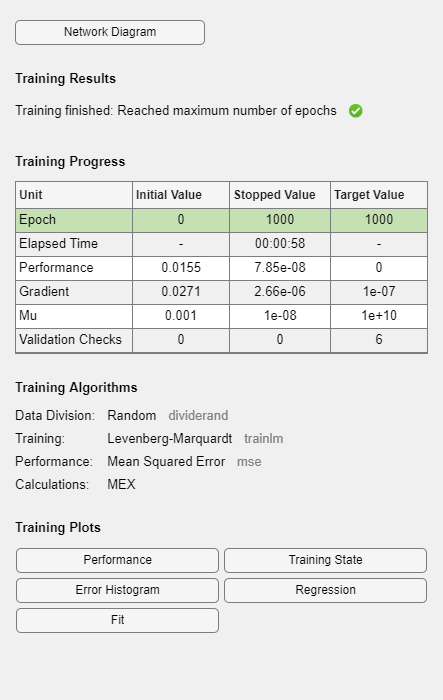

[net,tr] = train(net,normx,normy);

Test the NN for the given data

test = net(normx)

test =     0.8778    0.8774    0.8770    0.8766    0.8762    0.8758    0.8754    0.8749    0.8745    0.8740    0.8735    0.8730    0.8725    0.8720    0.8715    0.8709    0.8704    0.8699    0.8694    0.8688    0.8683    0.8678    0.8673    0.8668    0.8663    0.8658    0.8654    0.8649    0.8645    0.8642    0.8638    0.8636    0.8633    0.8631    0.8629    0.8628    0.8628    0.8627    0.8628    0.8629    0.8631    0.8633    0.8636    0.8639    0.8643    0.8648    0.8653    0.8658    0.8664    0.8671
    0.8993    0.8993    0.8994    0.8995    0.8996    0.8996    0.8996    0.8997    0.8997    0.8997    0.8996    0.8996    0.8996    0.8995    0.8994    0.8993    0.8991    0.8990    0.8988    0.8986    0.8983    0.8980    0.8977    0.8974    0.8970    0.8966    0.8962    0.8957    0.8951    0.8946    0.8940    0.8933    0.8926    0.8919    0.8911    0.8903    0.8895    0.8886    0.8877    0.8868    0.8859    0.8850    0.8841    0.8831    0.8822    0.8814    0.8805    0.8797    0.8789  

Test for 200 steps with initial input x0 = [-1.9 0 -0.9]

output = []%Initialize the output matrix


output =

     []



x0 = [-1.9 ; 0 ; -0.9]%Initial Value

x0 =    -1.9000
         0
   -0.9000


target = normy(:,1:200)%Set our target

target =     0.8779    0.8775    0.8772    0.8768    0.8763    0.8759    0.8755    0.8750    0.8746    0.8741    0.8736    0.8731    0.8726    0.8721    0.8716    0.8710    0.8705    0.8700    0.8695    0.8689    0.8684    0.8679    0.8674    0.8669    0.8664    0.8659    0.8655    0.8651    0.8647    0.8643    0.8640    0.8637    0.8635    0.8633    0.8632    0.8631    0.8630    0.8630    0.8631    0.8632    0.8634    0.8637    0.8640    0.8643    0.8647    0.8652    0.8657    0.8662    0.8668    0.8674
    0.8997    0.8998    0.8998    0.8999    0.8999    0.9000    0.9000    0.9000    0.9000    0.9000    0.8999    0.8999    0.8998    0.8997    0.8996    0.8994    0.8993    0.8991    0.8988    0.8986    0.8983    0.8980    0.8977    0.8973    0.8969    0.8965    0.8960    0.8955    0.8950    0.8944    0.8937    0.8931    0.8923    0.8916    0.8908    0.8900    0.8891    0.8883    0.8874    0.8865    0.8855    0.8846    0.8837    0.8828    0.8819    0.8810    0.8802    0.8794    0.8786

Normalize x0

normx0 = (((top-bottom)*(x0-data_min))/(data_max-data_min))+bottom

normx0 =     0.8793
    0.8996
    0.8900


Test the NN

normxk = net(normx0);%Calculate the next value
output = [output normxk]%Add xk to the output matrix

output =     0.8789
    0.8992
    0.8898


%Calculate the rest values
for i=1:199
    x_new =  net(output(:,end));
    output =  [output x_new];
end
output

output =     0.8789    0.8784    0.8779    0.8774    0.8769    0.8764    0.8759    0.8754    0.8748    0.8743    0.8738    0.8732    0.8726    0.8721    0.8715    0.8710    0.8704    0.8698    0.8693    0.8687    0.8682    0.8676    0.8671    0.8665    0.8660    0.8655    0.8650    0.8645    0.8641    0.8636    0.8632    0.8628    0.8624    0.8620    0.8617    0.8614    0.8611    0.8609    0.8606    0.8604    0.8602    0.8601    0.8600    0.8599    0.8599    0.8598    0.8598    0.8599    0.8600    0.8601
    0.8992    0.8989    0.8986    0.8984    0.8982    0.8980    0.8978    0.8977    0.8975    0.8974    0.8973    0.8971    0.8970    0.8969    0.8967    0.8966    0.8964    0.8963    0.8961    0.8959    0.8957    0.8955    0.8952    0.8949    0.8947    0.8943    0.8940    0.8936    0.8932    0.8928    0.8924    0.8919    0.8914    0.8908    0.8903    0.8897    0.8891    0.8884    0.8877    0.8870    0.8863    0.8856    0.8848    0.8841    0.8833    0.8826    0.8818    0.8811    0.8803

Denormalize the data

denorm_bottom = min(data(:))

denorm_bottom = -75.0001

denorm_top = max(data(:))

denorm_top = 0.0372


denorm_200_bottom = min(min(data(:,1:200)))

denorm_200_bottom = -15.2589

denorm_200_top = max(max(data(:,1:200)))

denorm_200_top = 0.0372


denorm_max_test = max(test(:))

denorm_max_test = 0.8997

denorm_min_test = min(test(:))

denorm_min_test = 0.1001


denorm_max_out = max(output(:))

denorm_max_out = 0.8992

denorm_min_out = min(output(:))

denorm_min_out = 0.7433


denorm = (((denorm_top-denorm_bottom)*(test-denorm_min_test))/(denorm_max_test-denorm_min_test))+denorm_bottom

denorm =    -2.0166   -2.0517   -2.0879   -2.1252   -2.1637   -2.2034   -2.2442   -2.2862   -2.3293   -2.3735   -2.4188   -2.4650   -2.5122   -2.5601   -2.6088   -2.6580   -2.7077   -2.7576   -2.8076   -2.8574   -2.9069   -2.9558   -3.0039   -3.0509   -3.0965   -3.1404   -3.1823   -3.2220   -3.2591   -3.2933   -3.3243   -3.3519   -3.3756   -3.3953   -3.4105   -3.4212   -3.4270   -3.4277   -3.4231   -3.4130   -3.3975   -3.3763   -3.3496   -3.3174   -3.2799   -3.2373   -3.1899   -3.1381   -3.0824   -3.0232
   -0.0017    0.0067    0.0143    0.0208    0.0264    0.0309    0.0342    0.0364    0.0372    0.0367    0.0348    0.0312    0.0261    0.0191    0.0103   -0.0006   -0.0136   -0.0288   -0.0465   -0.0668   -0.0898   -0.1156   -0.1444   -0.1764   -0.2117   -0.2505   -0.2927   -0.3387   -0.3883   -0.4418   -0.4991   -0.5602   -0.6251   -0.6936   -0.7657   -0.8411   -0.9194   -1.0005   -1.0837   -1.1687   -1.2548   -1.3415   -1.4281   -1.5138   -1.5981   -1.6803   -1.7596   -1.8356   -1.9077

denorm_out = (((denorm_200_top-denorm_200_bottom)*(output-denorm_min_out))/(denorm_max_out-denorm_min_out))+denorm_200_bottom

denorm_out =    -1.9594   -2.0063   -2.0541   -2.1027   -2.1520   -2.2020   -2.2528   -2.3042   -2.3563   -2.4090   -2.4624   -2.5162   -2.5706   -2.6253   -2.6804   -2.7356   -2.7910   -2.8464   -2.9016   -2.9565   -3.0111   -3.0650   -3.1182   -3.1704   -3.2217   -3.2717   -3.3203   -3.3674   -3.4129   -3.4566   -3.4983   -3.5381   -3.5756   -3.6109   -3.6439   -3.6744   -3.7024   -3.7278   -3.7504   -3.7703   -3.7874   -3.8015   -3.8127   -3.8208   -3.8259   -3.8280   -3.8268   -3.8226   -3.8152   -3.8047
    0.0372    0.0057   -0.0213   -0.0447   -0.0652   -0.0833   -0.0997   -0.1147   -0.1286   -0.1418   -0.1547   -0.1673   -0.1801   -0.1931   -0.2067   -0.2210   -0.2362   -0.2525   -0.2700   -0.2890   -0.3096   -0.3320   -0.3563   -0.3826   -0.4112   -0.4421   -0.4755   -0.5114   -0.5500   -0.5914   -0.6356   -0.6827   -0.7326   -0.7855   -0.8412   -0.8997   -0.9609   -1.0246   -1.0907   -1.1590   -1.2291   -1.3008   -1.3738   -1.4476   -1.5219   -1.5962   -1.6701   -1.7432   -1.

Calculate the error and the performance of the NN

per_error = 100*(abs(output - target))./abs(output)%Percentage error

per_error =     0.1093    0.0977    0.0865    0.0757    0.0655    0.0559    0.0468    0.0383    0.0304    0.0230    0.0163    0.0101    0.0045    0.0006    0.0053    0.0096    0.0134    0.0170    0.0204    0.0237    0.0270    0.0304    0.0341    0.0382    0.0430    0.0485    0.0550    0.0627    0.0718    0.0826    0.0952    0.1100    0.1270    0.1466    0.1690    0.1942    0.2226    0.2541    0.2889    0.3270    0.3685    0.4131    0.4608    0.5114    0.5646    0.6200    0.6772    0.7358    0.7951    0.8547
    0.0523    0.0970    0.1353    0.1683    0.1965    0.2207    0.2414    0.2589    0.2735    0.2856    0.2954    0.3030    0.3086    0.3124    0.3145    0.3150    0.3138    0.3112    0.3072    0.3017    0.2948    0.2866    0.2770    0.2661    0.2539    0.2403    0.2254    0.2091    0.1915    0.1726    0.1524    0.1311    0.1086    0.0851    0.0608    0.0358    0.0105    0.0150    0.0402    0.0649    0.0886    0.1108    0.1313    0.1496    0.1653    0.1781    0.1878    0.1941    0.1

avg_per_error = mean(per_error)%Average percentage error

avg_per_error =     0.0937    0.1035    0.1105    0.1151    0.1177    0.1187    0.1183    0.1166    0.1140    0.1105    0.1063    0.1074    0.1128    0.1183    0.1261    0.1332    0.1397    0.1456    0.1509    0.1556    0.1598    0.1635    0.1668    0.1696    0.1721    0.1742    0.1761    0.1776    0.1790    0.1801    0.1811    0.1821    0.1829    0.1838    0.1849    0.1861    0.1876    0.1995    0.2189    0.2386    0.2586    0.2786    0.2987    0.3187    0.3385    0.3579    0.3768    0.3951    0.4127    0.4295


NMSE = mse(output-target)/mean(var(target',1))%Normalized Mean Square Error

NMSE = 0.1104


perform(net,normy,test)

ans = 7.9152e-08

perform(net,target,output)

ans = 8.1135e-05


perform(net,y,denorm)

ans = 0.0014

perform(net,y(:,1:200),denorm_out)

ans = 0.7299

Export the output

save('data_VAL.mat',"denorm_out");

Plot the results and compare with the original function

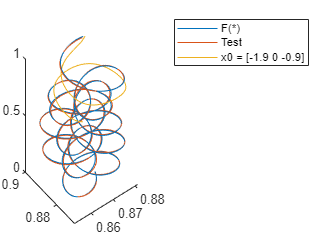

figure;
plot3(norm_data(1,1:end),norm_data(2,1:end),norm_data(3,1:end));%Plot the original normalized function
hold on;
plot3(test(1,1:end),test(2,1:end),test(3,1:end))%Plot the normalized output of the NN for the training data
hold on;
plot3(output(1,1:end),output(2,1:end),output(3,1:end))%Plot the normalized output of NN for the 200 first steps for x0=[-1.9 0 -0.9]
legend('F(*)','Test','x0 = [-1.9 0 -0.9]')

Plot the denormalized data

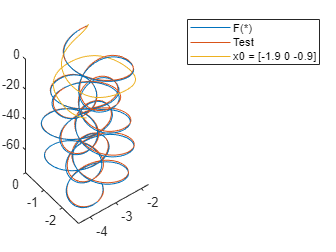

figure;
plot3(data(1,1:end),data(2,1:end),data(3,1:end))%Plot the original function
hold on;
plot3(denorm(1,1:end),denorm(2,1:end),denorm(3,1:end))%Plot the output of the NN for the training data
hold on;
plot3(denorm_out(1,1:end),denorm_out(2,1:end),denorm_out(3,1:end))%Plot the output of the NN for 200 first steps for x0=[-1.9 0 -0.9]
legend('F(*)','Test','x0 = [-1.9 0 -0.9]')